## **Driver test program to check Clothoids library**

**Clothods list**

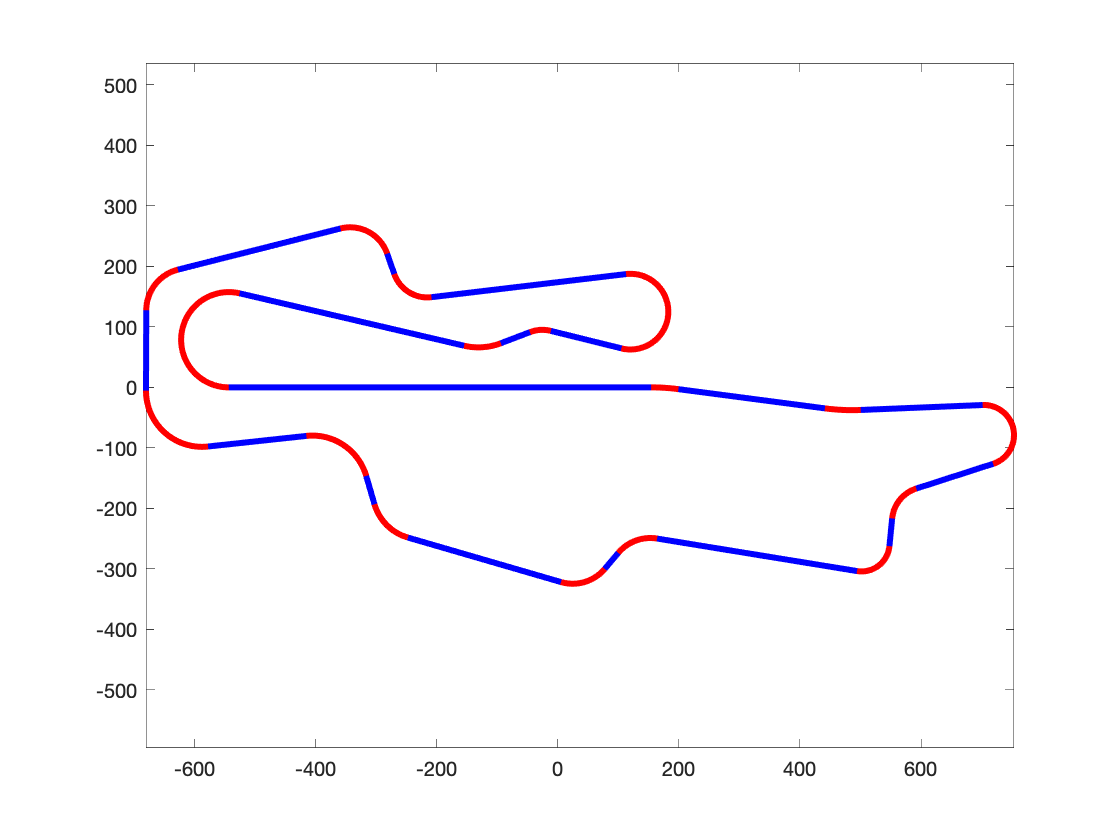

close all;

x0     = 0;
y0     = 0;
theta0 = 0;

S = ClothoidList();
% STRAIGHT LINE      START GRID
S.push_back( x0, y0, theta0, 0, 0, 153.950959920426 ); % first segment

addseg  = @(a,r) S.push_back( -1/r, 0, abs(a*r) );
addseg1 = @(l) S.push_back( 0, 0, l );

% CORNER:
addseg(45.2707044337391/347.327792187656,347.327792187656);

% STRAIGHT LINE
addseg1(244.134389610089);

%  CORNER
addseg(59.358551236732/347.327792187656,-347.327792187656);

% STRAIGHT LINE
addseg1(201.644854584327);

% CORNER (San Donato)
addseg(142.894358535785/49.7836502135641,49.7836502135641);

% STRAIGHT LINE
addseg1(133.43893827313);

% CORNER (Luco) 
addseg(67.1863934651959/57.8879653646094,-57.8879653646094);

% STRAIGHT LINE
addseg1(45.9584134622707);

% CORNER (Poggio Secco)
addseg(75.6533188312851/46.3103722916875,46.3103722916875);

% STRAIGHT LINE
addseg1(334.716783157046);

% CORNER (Materassi) 													
addseg(71.4573675497968/69.4655584375313,-69.4655584375313);

% STRAIGHT LINE
addseg1(34.6598403824062);

% CORNER: (Borgo San Lorenzo)
addseg(79.9150308414277/69.4655584375313,69.4655584375313);

% STRAIGHT LINE
addseg1(263.472674871652);

% CORNER: (Casanova) 
addseg(81.3041104583168/81.0431515104532,81.0431515104532);

% STRAIGHT LINE
addseg1(48.7678321973459);

% CORNER: (Savelli) 
addseg(129.057513950613/92.6207445833751,-92.6207445833751);

% STRAIGHT LINE
addseg1(163.432545543426);

% CORNER: (Arrabbiata1)  
addseg(155.737382531577/92.6207445833751,92.6207445833751);

% STRAIGHT LINE
addseg1(132.80865410624);

% CORNER: (Arrabbiata2)
addseg(91.6653616029976/69.4655584375313,69.4655584375313);

% STRAIGHT LINE
addseg1(276.98025270983)

% CORNER: (Scarperia)
addseg(96.1313023549464/64.8345212083625,64.8345212083625);

% STRAIGHT LINE
addseg1(35.6152233627838)

% CORNER: (Palagio)
addseg(78.3247326569311/57.8879653646094,-57.8879653646094);

% STRAIGHT LINE
addseg1(323.774799943827)

% CORNER: (Correntaio)
addseg(218.995961770854/62.5190025937782,62.5190025937782);

% STRAIGHT LINE
addseg1(120.082100696761);

% CORNER: (Biondetti1)
addseg(35.1331323872273/57.8879653646094,-57.8879653646094);

% STRAIGHT LINE
addseg1(51.5168158965805);

% CORNER: (Biondetti2)
addseg(61.7963292341664/104.198337656297,104.198337656297);

% STRAIGHT LINE
addseg1(380.85511241567);

% CORNER: (Bucine)  
addseg(265.379041347039/78.7276328958688,-78.7276328958688);

% STRAIGHT LINE
%addseg1(543.929215677558);
S.push_back_G1( x0, y0, theta0 ); % first segment

S.plot();
axis equal


S.save('Mugello.txt',10);